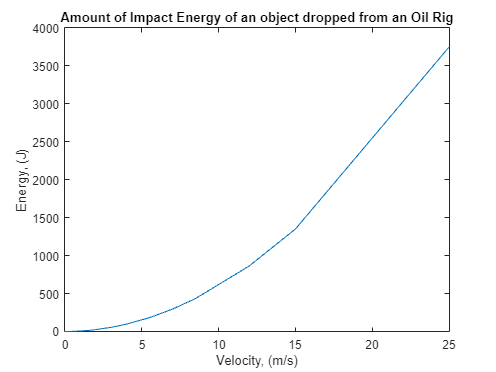

% Velocity Experiment
% An mlx file which graphs the provided values of X vs Energy from an
% experiment involving objects dropped from oil rigs before
% showing this to the user and printing 3 lines regarding the actual
% form of Energy, what the unknown variable X is and an estimation of the
% mass of the object.
%
% Jephrey Bird
% 02/11/2023

% Begin

% First we create two arrays with which to house the values of X and Energy
% we have been provided with.
X = [0, 0.1, 0.2, 0.5, 0.8, 1.5, 2, 3, 4, 5.5, 7, 8.5, 12, 15, 25];
Energy = [0, 0.06, 0.24, 1.5, 3.84, 13.5, 24, 54, 96, 181.5, 294, 433.5, 864, 1350, 3750];

% We then use polyfit against the arrays to ascertain a mathematical 
% relationship between the two. Due to the graph having a potential 
% exponential function (and later calculations confirming this) we will 
% estimate this to the second degree.
graphCoeffs = polyfit(X, Energy, 2);
% This comes to a mathematical relationship of with a coefficient of 6 in
% the squared column and the x and constant values are too low to consider
% as relevant

% After having received our coefficients we can now plot the coefficients
% against the values of X to get what the Energy would be at a given X and
% generate a 2nd order line of best fit.
relVal = polyval(graphCoeffs, X);

% We now create a figure and plot all the relevant details onto it
% including the line, title, and labels.
figure
plot(X, relVal)
title("Amount of Impact Energy of an object dropped from an Oil Rig")
xlabel("Velocity, (m/s)")
ylabel("Energy, (J)")


% Lastly we need to figure out what equation we are using. Due to height we 
% are likely using either kinetic energy or the representation of 
% gravitational potential energy. As the relationship from the graph shows, it 
% will more likely be Kinetic energy so we will arrange the equation to estimate 
% the mass.

% Using the pair when x = 0.1
% > KE = 0.5 * mass * Velocity^2
% > 0.06 = 0.5 * mass * 0.1^2 (Estimating that X may be the velocity)
% > 2 * 0.06 / 0.1^2 = mass
% > 12 = mass
% So we can assume mass is 12kg but can test that on another point, taking
% x = 25:
% > KE = 0.5 * mass * Velocity^2
% > KE = 0.5 * 12 * 25^2
% > KE = 0.5 * 12 * 25^2
% > KE = 3750
% As this matches, we take 12kg as correct and display the lines below as
% requested by the exercise
disp("The form of Energy is Kinetic Energy.")

The form of Energy is Kinetic Energy.


disp("The unknown variable, X is Velocity, its units are Metres/Second.")

The unknown variable, X is Velocity, its units are Metres/Second.


disp("An estimate of the mass of the object is 12kg.")

An estimate of the mass of the object is 12kg.



% End

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Program Outputs
% Velocity Experiment

% The form of Energy is Kinetic Energy.
% The unknown variable, X is Velocity, its units are Metres/Second.
% An estimate of the mass of the object is 12kg.

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%